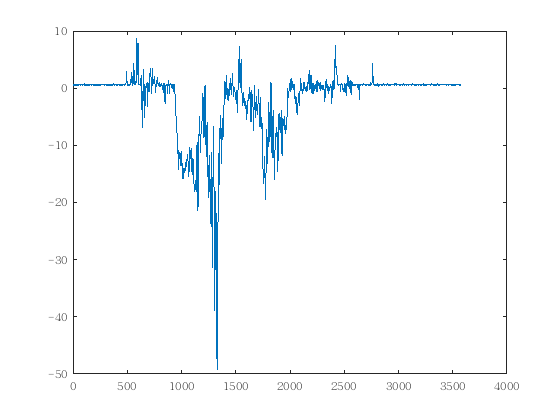

clear all
data=textread('AHRS/data/memsData1.txt');
dT=0.005;
plot(data(:,3));

%角速度去零飘处理
dT=0.005;
staticNum=400;static=399;
wx=data(staticNum:end,1)-mean(data(staticNum-static:staticNum,1));
wy=data(staticNum:end,2)-mean(data(staticNum-static:staticNum,2));
wz=(data(staticNum:end,3)-mean(data(staticNum-static:staticNum,3)));

%加速度计归一化处理
axRaw=data(staticNum:end,4);
ayRaw=data(staticNum:end,5);
azRaw=data(staticNum:end,6);
normAcc=sqrt(sum(data(staticNum:end,4:6).^2,2));
ax=axRaw./normAcc;
ay=ayRaw./normAcc;
az=azRaw./normAcc;

%积分量初始化
initEuler=[atan2d(-ay(1),-az(1)) asind(ax(1)) zeros(length(ax(1)),1)];%欧拉角初始化
initQuaternion=euler2quat_self(initEuler);%四元数初始化
quaternion=initQuaternion;
qEKF=initQuaternion';
n=length(wx);
GyroAngle=zeros(n,3);
EKFAngle=zeros(n,3);
P_k=[0.625 0.015 0.015 0.015;0.015 0.625 0.015 0.015;0.015 0.015 0.625 0.015;0.015 0.015 0.015 0.625;]*0.0001;
ratio=4;
Q_k=eye(4)*0.00001;         %状态转移方程噪声
R_k=eye(3)*0.00001*ratio;   %测量噪声
for i=1:n
    %纯陀螺仪的积分
    quaternion=quatInt(quaternion,[wx(i);wy(i);wz(i)],dT);
    GyroAngle(i,1:3)=quat2euler_self(quaternion);
    %计算状态转移矩阵
    A_k=figureA_k([wx(i);wy(i);wz(i)],dT);
    qEKF=A_k*qEKF;
    P_k=A_k*P_k*A_k'+Q_k;
    %因为实际加速度计坐标系与参考文献中的想法，因此在H_k与h_k前添加负号
    H_k=-[-2*qEKF(3) 2*qEKF(4) -2*qEKF(1) 2*qEKF(2);2*qEKF(2) 2*qEKF(1) 2*qEKF(4) 2*qEKF(3);2*qEKF(1) -2*qEKF(2) -2*qEKF(3) 2*qEKF(4)];
    K_k=P_k*H_k'/(H_k*P_k*H_k'+R_k);
    Z_k=[ax(i) ay(i) az(i)]';
    h_k=-[2*qEKF(2)*qEKF(4)-2*qEKF(1)*qEKF(3);2*qEKF(1)*qEKF(2)+2*qEKF(3)*qEKF(4);qEKF(1)^2-qEKF(2)^2-qEKF(3)^2+qEKF(4)^2];
    Vx=K_k*(Z_k-h_k);
    qEKF=qEKF+Vx;
    P_k=(eye(4)-K_k*H_k)*P_k;
    %航向角不参与融合
    eulerT=quat2euler_self(qEKF);
    eulerT(3)=GyroAngle(i,3);
    qEKF=euler2quat_self(eulerT)';
    normX=sqrt(sum(qEKF.^2));
    qEKF=qEKF/normX;
    EKFAngle(i,1:3)=quat2euler_self(qEKF);
end  

%纯加速度计算出的角度
AccAngle=[atan2d(-ay,-az) asind(ax) zeros(length(ax),1)];

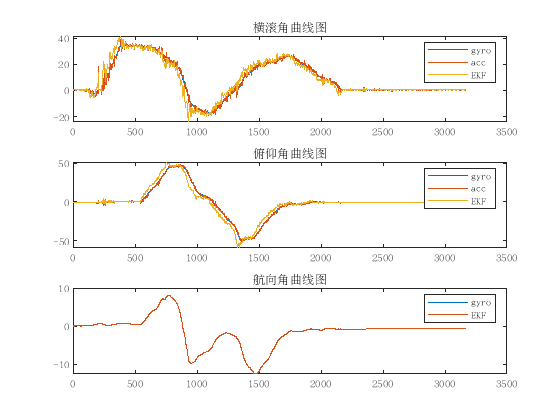

%画图
figure
subplot(311);
plot(GyroAngle(:,1));hold on;
plot(AccAngle(:,1));hold on;
plot(EKFAngle(:,1));
title('横滚角曲线图')
legend('gyro','acc','EKF');
subplot(312);
plot(GyroAngle(:,2));hold on;
plot(AccAngle(:,2));hold on;
plot(EKFAngle(:,2));
title('俯仰角曲线图')
legend('gyro','acc','EKF');
subplot(313);
plot(GyroAngle(:,3));hold on;
plot(EKFAngle(:,3));
title('航向角曲线图')
legend('gyro','EKF');

function [A_k] = figureA_k(palstance,dT)
    A_k=[ 0 -palstance(1) -palstance(2) -palstance(3) ;
          palstance(1) 0 palstance(3) -palstance(2) ;
          palstance(2) -palstance(3) 0 palstance(1) ;
          palstance(3) palstance(2) -palstance(1) 0 ; ];
    A_k=eye(4)+A_k*0.5*dT;
end